# Deconvolution Benchmark: Matlab (deconSingle)

addpath("WBDeconvolution/")

## Test Image

img = single(imread('ImagenPrueba.jpg'));

Array indices must be positive integers or logical values.

psf = single(imread('psf.jpg'));

output = DeconSingleView_fn(img,psf);

Unrecognized function or variable 'img'.

f = @() DeconSingleView_fn(img,psf); 

timeit(f)

## Cell

img = single(imread("cells3d_convolved.tif"));
psf = single(imread("cells3d_psf.tif"));

output2 = DeconSingleView_fn(img,psf);

f = @() DeconSingleView_fn(img,psf); 

timeit(f) % in seconds

## Cube of Spherical Beads

imgCube = tiffreadVolume('cubeConvolved.tif');
psfCube = tiffreadVolume('PSF.tif');

outputCube = DeconSingleView_fn(imgCube,psfCube);

f = @() DeconSingleView_fn(imgCube,psfCube); 
timeit(f) % in seconds

## _______________________________________________________________________

## C. Elegans embryo

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), 'single');
    
    % Leer el rango de valores para normalización
    max_val = double(max(first_image(:)));  % Valor máximo para normalización

    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        img = imread(fullfile(folder_path, files(i).name));
        % Convertir la imagen a single y normalizar
        image_stack(:, :, i) = single(img) / max_val;
    end
end



imageStack=ones(5,5);
imageStack(2,2)=2.5;
imageStack(3,3)=2.8;
imageStack(4,4)=2;
imageStack(2,3)=1.5;
imageStack(2,4)=2.5;
imageStack(3,2)=2.8

imageStack =     1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    2.5000    1.5000    2.5000    1.0000
    1.0000    2.8000    2.8000    1.0000    1.0000
    1.0000    1.0000    1.0000    2.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000


psfStack=zeros(5,5);
psfStack(2:4,2:4)=1

psfStack =      0     0     0     0     0
     0     1     1     1     0
     0     1     1     1     0
     0     1     1     1     0
     0     0     0     0     0


deconvTEST = DeconSingleView_fn(imageStack,psfStack)

Preprocessing forward and back projectors ...


PSFIn =      0     0     0     0     0
     0     1     1     1     0
     0     1     1     1     0
     0     1     1     1     0
     0     0     0     0     0


PSF1 =          0         0         0         0         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0         0         0         0         0


PSF2 =          0         0         0         0         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0         0         0         0         0


PSF_fp =          0         0         0         0         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0         0         0         0         0


PSF_bp =          0         0         0         0         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0    0.1111    0.1111    0.1111         0
         0         0         0         0         0


OTF_bp =     1.0000    0.5393   -0.2060   -0.2060    0.5393
    0.5393    0.2909   -0.1111   -0.1111    0.2909
   -0.2060   -0.1111    0.0424    0.0424   -0.1111
   -0.2060   -0.1111    0.0424    0.0424   -0.1111
    0.5393    0.2909   -0.1111   -0.1111    0.2909


OTF_fp =     1.0000    0.5393   -0.2060   -0.2060    0.5393
    0.5393    0.2909   -0.1111   -0.1111    0.2909
   -0.2060   -0.1111    0.0424    0.0424   -0.1111
   -0.2060   -0.1111    0.0424    0.0424   -0.1111
    0.5393    0.2909   -0.1111   -0.1111    0.2909


Start deconvolution...


stackEstimate = 5×5 single matrix
    0.9514    0.9341    1.0326    0.9499    0.9643
    0.9892    2.6217    1.7243    2.4326    0.8940
    0.9798    2.8784    3.3882    1.0499    0.9747
    0.9542    1.0045    1.0615    1.9324    0.9139
    0.8756    0.8339    0.8953    0.9092    0.9546


Deconvolution completed !!!


deconvTEST = 5×5 single matrix
    0.9514    0.9341    1.0326    0.9499    0.9643
    0.9892    2.6217    1.7243    2.4326    0.8940
    0.9798    2.8784    3.3882    1.0499    0.9747
    0.9542    1.0045    1.0615    1.9324    0.9139
    0.8756    0.8339    0.8953    0.9092    0.9546


deconvTEST = DeconSingleView_fn(imageStack,psfStack)

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


deconvTEST = 5×5 single matrix
    1.1276    0.0973    2.3160    0.7595    1.3539
    2.1167    2.3834    3.1154    0.3922    0.0049
    0.9742    0.0803    7.2306    0.9440    1.3076
    1.2563    2.5013    0.8158    1.3955    0.0541
    0.0171    0.0010    0.0010    0.1492    2.7054


### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = '/Users/yi/TFGNotebook/CElegans-CY3';
psfPath1 = '/Users/yi/TFGNotebook/PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);
psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(179:534,169:504, :);

%image_stack1 = image_stack1(1:356, 1:336, 52);
% Obtener las dimensiones de image_stack
disp(size(image_stack1))

   356   336   104



% Obtener las dimensiones de psf_stack
disp(size(psf_stack1))

   356   336   104



outputChannel1 = DeconSingleView_fn(image_stack1,psf_stack1);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


outputChannel1(:,:,52)

ans = 356×336 single matrix
    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010 

% Seleccionar el stack 52
stack_52 = outputChannel1(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '1iter_outputChannel1.png');

f = @() DeconSingleView_fn(image_stack1,psf_stack1); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 115.0504

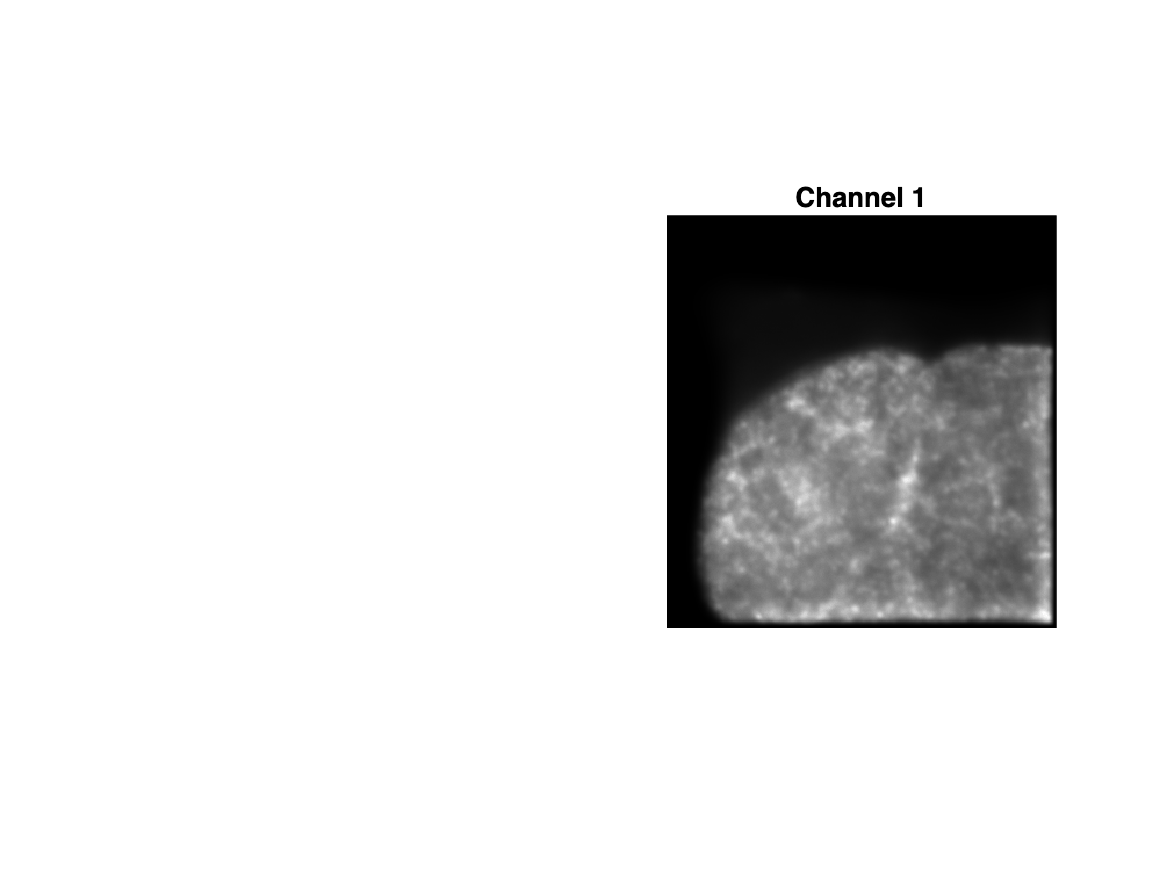

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel1(:, :, 52),[]);

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;

### Canal 2

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath2 = '/Users/yi/TFGNotebook/CElegans-DAPI';
psfPath2 = '/Users/yi/TFGNotebook/PSF-CElegans-DAPI';

% Cargar las imágenes en una matriz 3D
image_stack2 = load_image_stack(imagePath2);
psf_stack2 = load_image_stack(psfPath2);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack2 = image_stack2(1:356, 1:336, :);
psf_stack2 = psf_stack2(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack2));

   356   336   104



disp(size(psf_stack2));

   305   305   104



outputChannel2 = DeconSingleView_fn(image_stack2,psf_stack2);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


% Seleccionar el stack 52
stack_522 = outputChannel2(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized2 = uint8(255 * mat2gray(stack_522)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized2, 'stack_52_outputChannel2.png');

f = @() DeconSingleView_fn(image_stack2,psf_stack2); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 10.7247

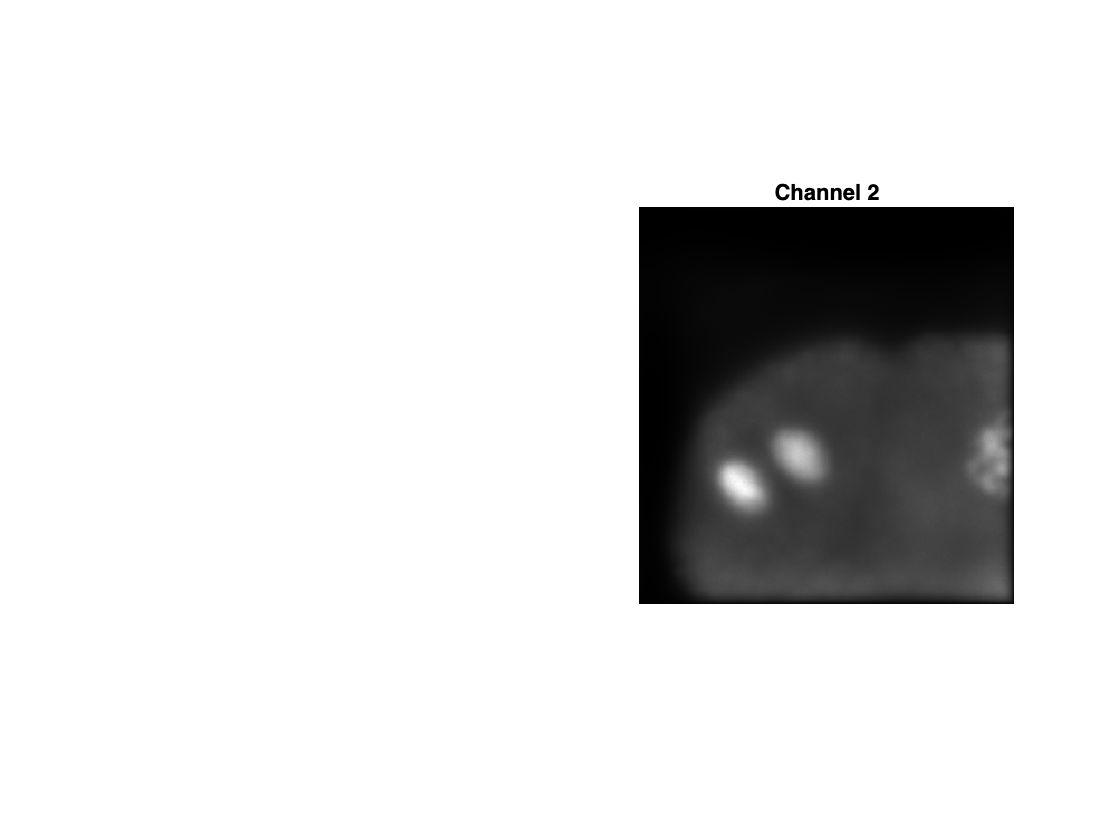

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel2(:, :, 52),[]);

% Añadir título
title('Channel 2');

% Desactivar los ejes
axis off;

### Canal 3

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath3 = '/Users/yi/TFGNotebook/CElegans-FITC';
psfPath3 = '/Users/yi/TFGNotebook/PSF-CElegans-FITC';

% Cargar las imágenes en una matriz 3D
image_stack3 = load_image_stack(imagePath3);
psf_stack3 = load_image_stack(psfPath3);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack3 = image_stack3(1:356, 1:336, :);
psf_stack3 = psf_stack3(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack3));

   356   336   104



disp(size(psf_stack3));

   305   305   104



outputChannel3 = DeconSingleView_fn(image_stack3,psf_stack3);

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


% Seleccionar el stack 52
stack_523 = outputChannel3(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized3 = uint8(255 * mat2gray(stack_523)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized3, 'stack_52_outputChannel3.png');

f = @() DeconSingleView_fn(image_stack3,psf_stack3); 
T = timeit(f) % in seconds

Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!
Preprocessing forward and back projectors ...
Start deconvolution...
Deconvolution completed !!!


T = 17.4314

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(outputChannel3(:, :, 52),[]);

% Añadir título
title('Channel 3');

% Desactivar los ejes
axis off;

### Combinación de canales

function normalized_image = normalize(image)
    min_val = double(min(image(:)));  % Convertir a double para evitar problemas con uint16
    max_val = double(max(image(:)));
    if min_val == max_val
        normalized_image = zeros(size(image), 'like', image);  % Usar el mismo tipo de datos
    else
        normalized_image = (double(image) - min_val) / (max_val - min_val);
    end
end

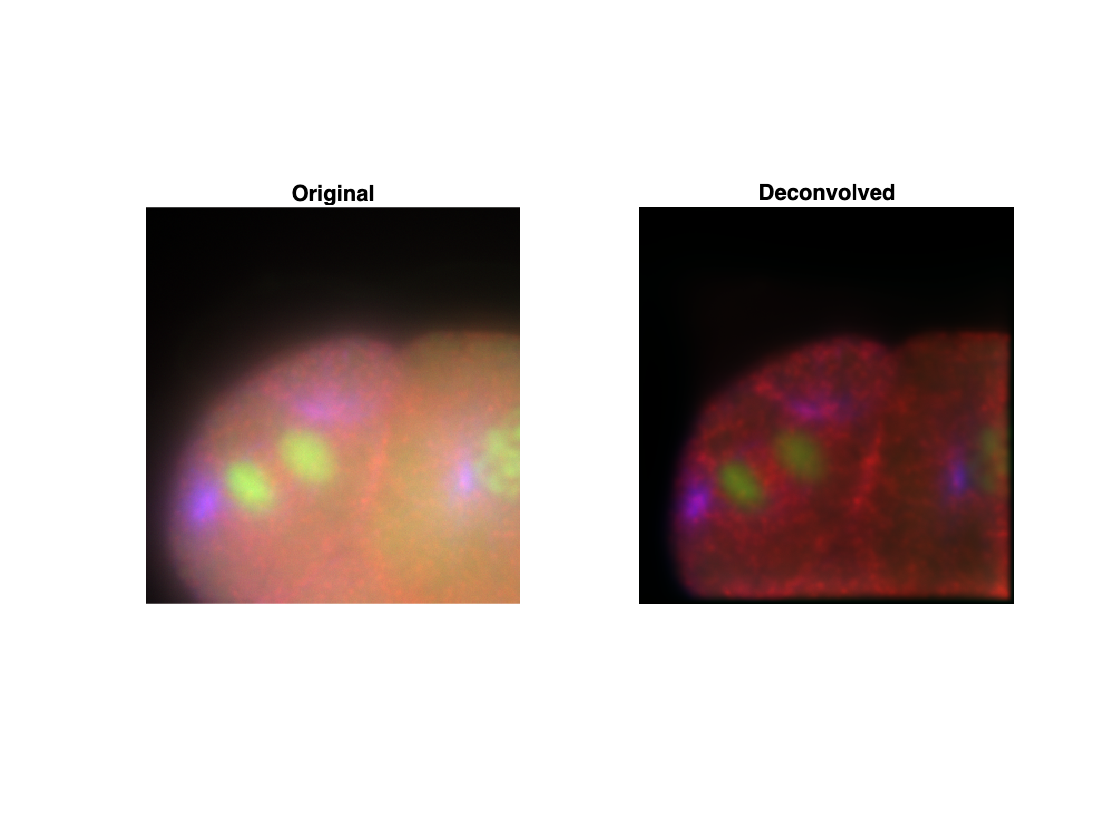


% Normalizar los canales (opcional, pero recomendado)
deconvolved_stack_R = normalize(outputChannel1);
deconvolved_stack_G = normalize(outputChannel2);
deconvolved_stack_B = normalize(outputChannel3);

% Combinar los tres canales en una sola matriz 4D (altura, ancho, profundidad, canales)
deconvolved_stack_color = cat(4, deconvolved_stack_R, deconvolved_stack_G, deconvolved_stack_B);


% Visualizar un plano específico de la imagen deconvolucionada en color
figure;

subplot(1, 2, 1);
original_image_R = normalize(image_stack1(:, :, 52));
original_image_G = normalize(image_stack2(:, :, 52));
original_image_B = normalize(image_stack3(:, :, 52));
original_image_color = cat(3, original_image_R, original_image_G, original_image_B);
imshow(original_image_color);
title('Original');
axis off;

subplot(1, 2, 2);
deconvolved_image_color = squeeze(deconvolved_stack_color(:, :, 52, :));  % Convertir 4D a 3D para mostrar
imshow(deconvolved_image_color);
title('Deconvolved');
axis off;

% Guardar imagen PNG
imwrite(deconvolved_image_color, 'deconvolved_CElegans_deconSingle.png');

%Guardar imagen original
%imwrite(original_image_color, 'ImagenORIGINAL.png');